# Assignment #2

Connor Cavarretta

ECE 651

09/21/2025

## Question 3.2

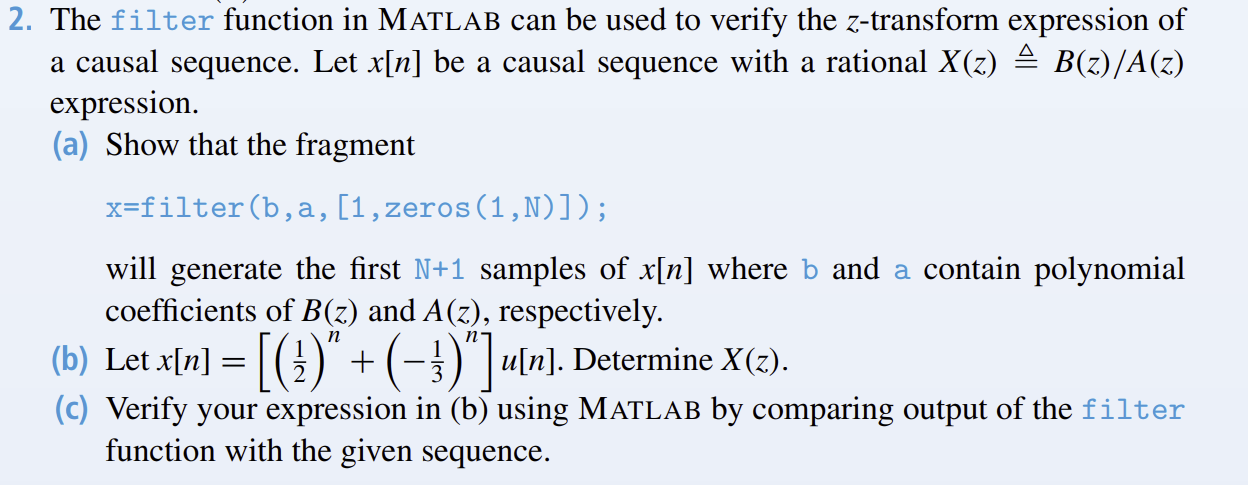

a1 = [1 -0.5];
a2 = [1  1/3];
A  = conv(a1, a2);      % denominator
B  = a1 + a2;           % numerator

%% Generate samples with filter
N = 30;
imp = [1 zeros(1,N)];
x_filter = filter(B, A, imp);

%% Compare with closed-form sequence
n = 0:N;
x_true = (1/2).^n + (-1/3).^n;

disp(['Max abs error = ', num2str(max(abs(x_filter - x_true)))])

Max abs error = 3.4694e-18


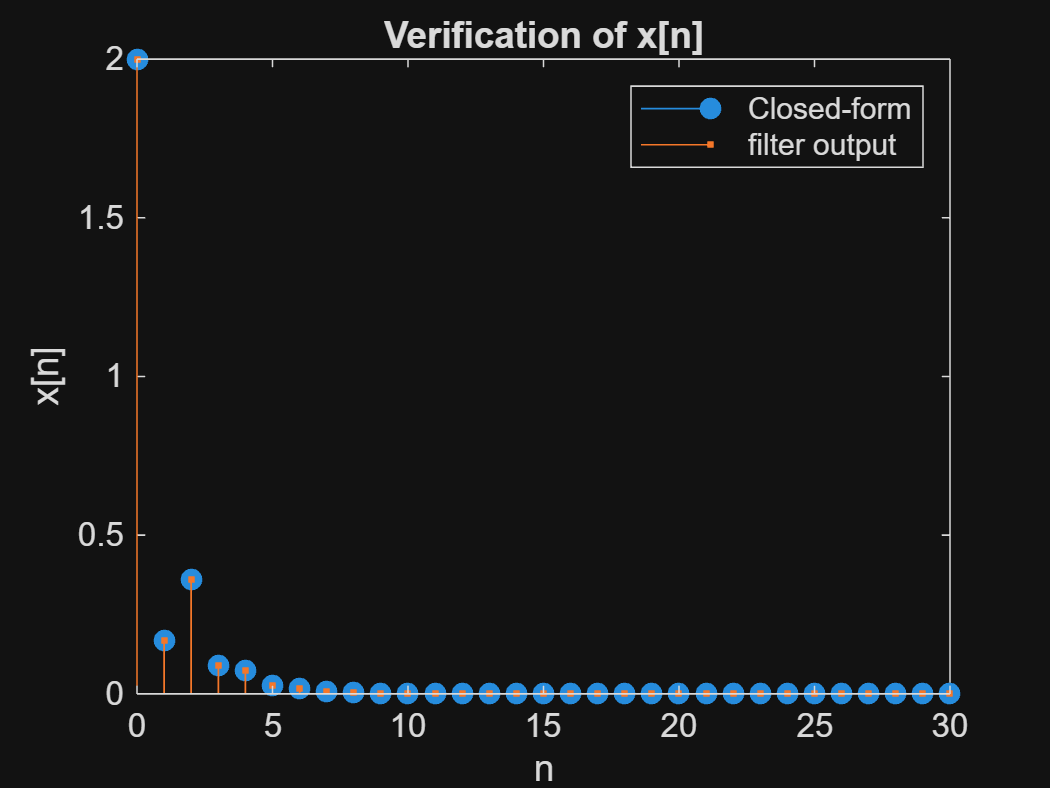

figure;
stem(n, x_true, 'filled'); hold on
stem(n, x_filter, '.')
xlabel('n'); ylabel('x[n]')
legend('Closed-form','filter output')
title('Verification of x[n]')

## Question 3.27

## 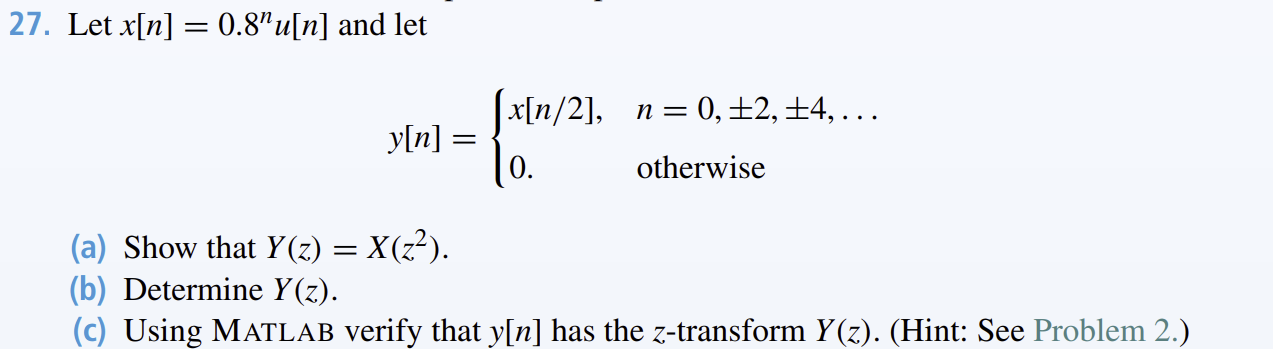

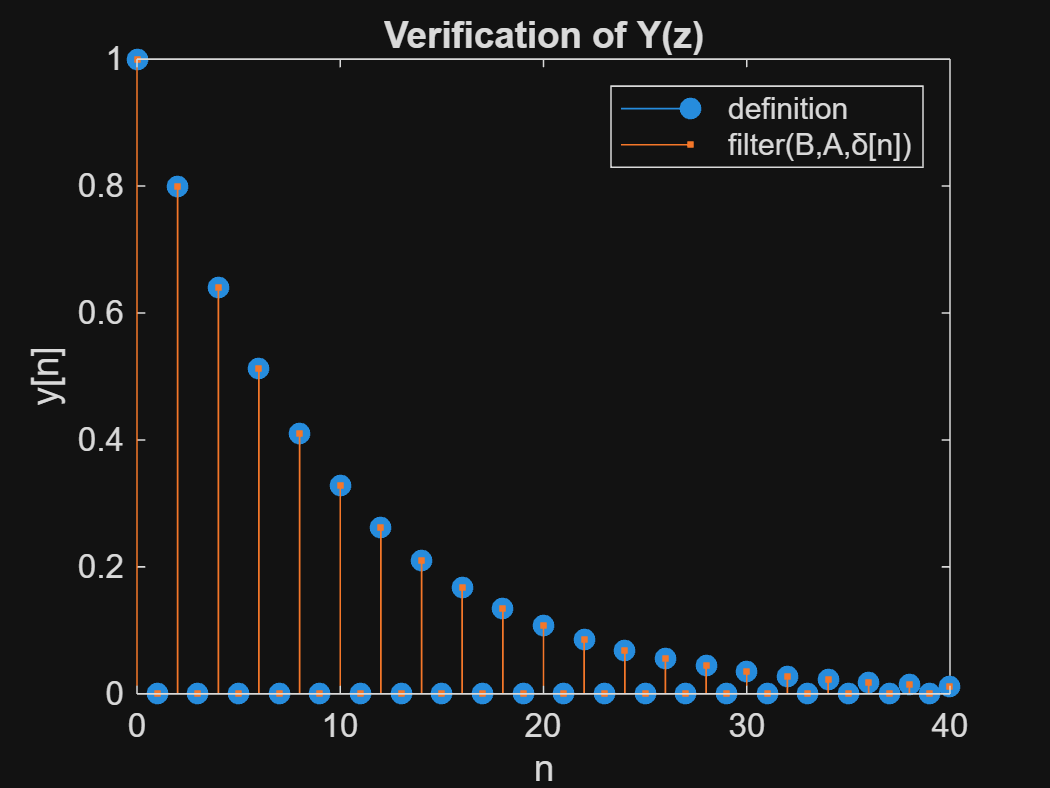

%% Determine Y(z) = B(z)/A(z)
B = 1;               % numerator
A = [1 0 -0.8];      % denominator

%% Verify
N = 40;
imp = [1 zeros(1,N)];
y_filter = filter(B, A, imp);        

n = 0:N;
x = (0.8).^n;                        
y_def = zeros(1,N+1);                
y_def(1:2:end) = x(1:floor(N/2)+1);

figure;
stem(n, y_def, 'filled'); hold on
stem(n, y_filter, '.')
xlabel('n'); ylabel('y[n]')
legend('definition','filter(B,A,δ[n])'); title('Verification of Y(z)')

## Question 3.29

## 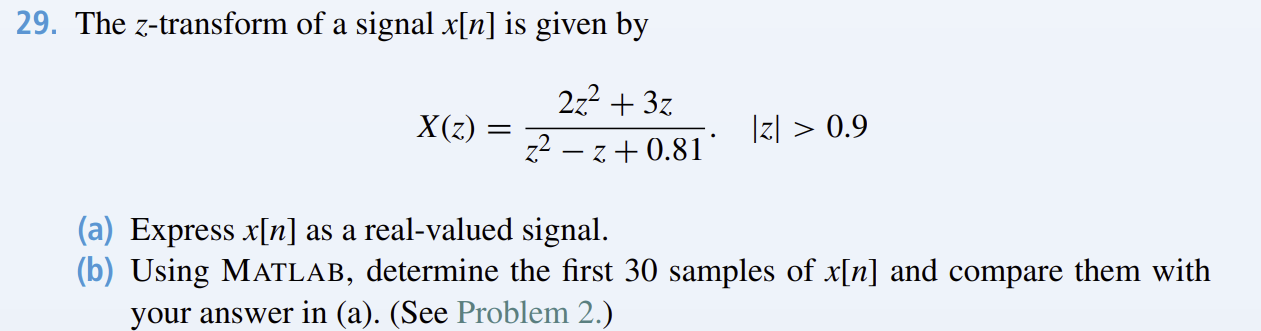

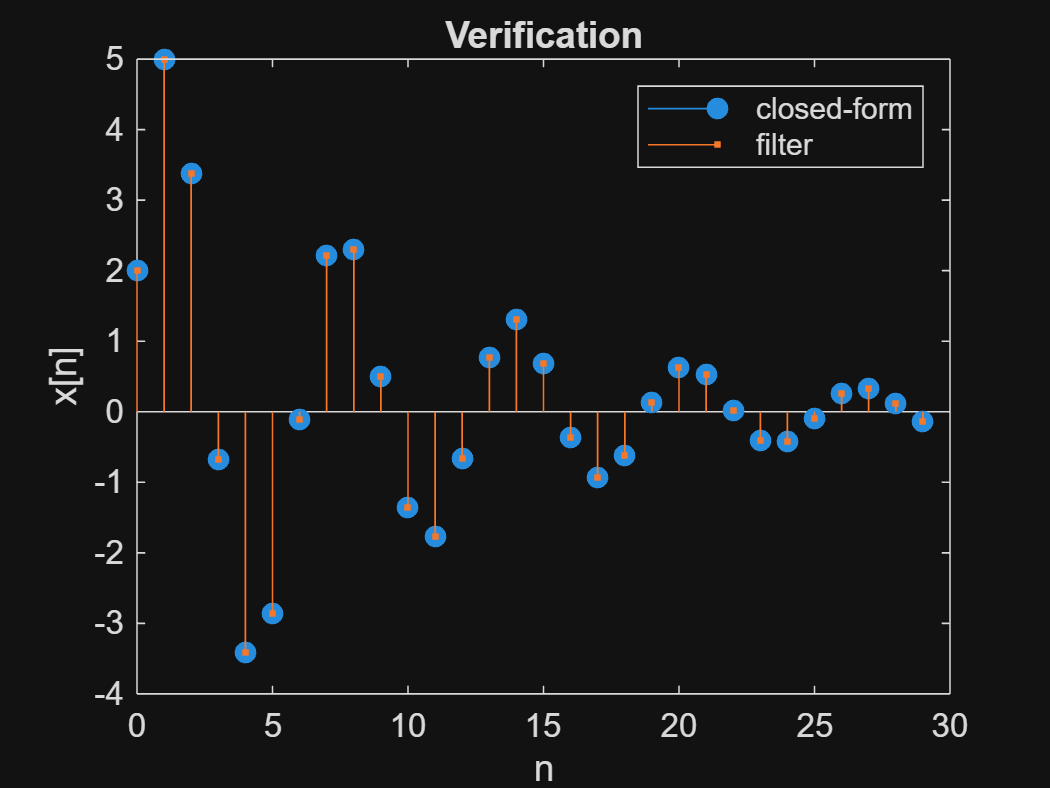

%% Real-time signal x[n] from X(z)
% X(z) = (2 + 3 z^{-1}) / (1 - z^{-1} + 0.81 z^{-2}),  ROC: |z|>0.9 (causal)
rho = 0.9;                                % pole radius
theta = acos(5/9);                        % angle; cos(theta)=0.5/0.9
k = 2.672612419;                          % = 10/sqrt(14)
% x[n] = 2*rho^n*(cos(n*theta) + k*sin(n*theta)) u[n]

%% First 30 samples via filter and compare to (a)
b = [2 3]; a = [1 -1 0.81];
N = 29; n = 0:N;

x_filter = filter(b, a, [1 zeros(1,N)]);
x_closed = 2 * (rho.^n) .* (cos(n*theta) + k*sin(n*theta));

figure;
stem(n, x_closed, 'filled'); hold on
stem(n, x_filter, '.'); xlabel n; ylabel('x[n]')
legend('closed-form','filter'); title('Verification')

## Question 3.43

## 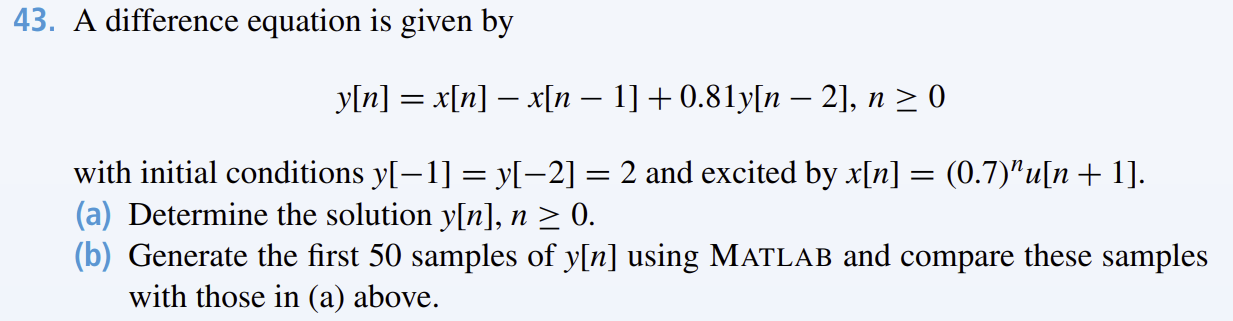

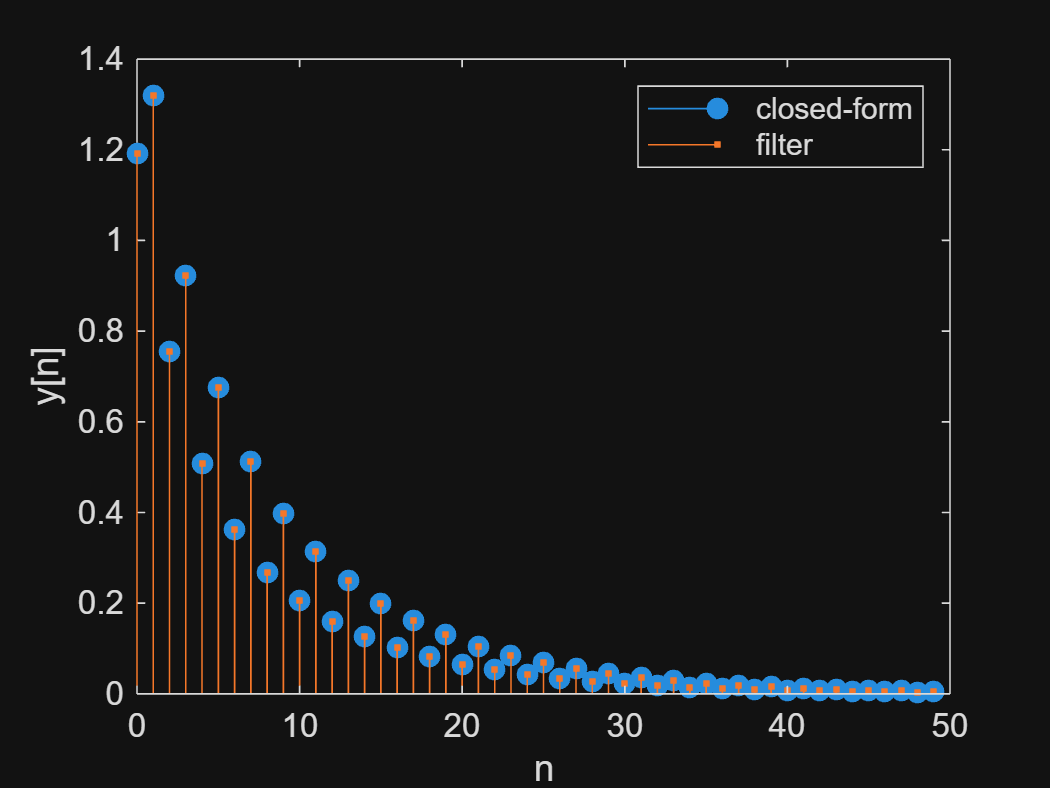

%% Generate samples
b = [1 -1 0];               % x[n] - x[n-1]
a = [1 0 -0.81];            % y[n] - 0.81 y[n-2]
N = 49; n = 0:N;

x = (0.7).^n;               
x_m1 = 1/0.7; x_m2 = 0;     
zi = filtic(b, a, [2 2], [x_m1 x_m2]);   
y_filter = filter(b, a, x, zi);

C1 = 261/350; C2 = -1179/5600; A = 21/32;
y_closed = C1*(0.9).^n + C2*(-0.9).^n + A*(0.7).^n;

figure;
stem(n,y_closed,'filled'); hold on, stem(n,y_filter,'.')
legend('closed-form','filter'); xlabel n; ylabel('y[n]');